# Example 2: Using +microstate toolbox for MEG ERF microstate analysis

This example will perform single-subject, between-trial microstate analysis of MEG ERFs using the +microstate toolbox. The data used in this example consists of many trials of MEG data recorded following congruent and incongruent sentences. The Fieldtrip cluster-permutation tutorial analyses this data and identified spatiotemporal clusters of electrodes and samples which significantly differ between conditions [1,2]. Here, we will use topographic microstate analysis [3] to test the hypothesis these differences are due to differences in activation of a microstate with activation patterns reflecting the spatial ERF differences. 

This example will reproduce the analysis described in section 3.2 of the toolbox manuscript (Tait and Zhang, 2021). 

References: 

[1] [https://www.fieldtriptoolbox.org/tutorial/cluster_permutation_timelock/](https://www.fieldtriptoolbox.org/tutorial/cluster_permutation_timelock/) 

[2] Tait and Zhang (2021) In preparation

[3] Murray et al. (2008) Brain Topogr 20:249:264

Luke Tait, May 2021

### Load the data and format into a +microstate cohort

The data used in this tutorial was downloaded and preprocessed as described in the Fieldtrip tutorial for cluster permutation analysis of MEG ERFs [1]. The code used for this preprocessing can be found in microstate_toolbox/examples/preprocessing_scripts/example2.m.

% Load in the data
clear, clc, close all
load('example2_data.mat','dataFIC_LP','dataFC_LP')

For a between-trial design, we can view the +microstate *cohort *object as the participant, and each trial as the individuals in the *cohort*. Initialize a *cohort* object:

% Initialize a cohort
coh = microstate.cohort ; 

Next, upload the incongruent trials, stored in `dataFIC_LP`. To do so, we will make a loop over trials which consists of two stages. Firstly, we make a microstate *individual *object for a given trial, specifying that the data is MEG data. Then, we use the **add_individuals** command for the *cohort* object to add the *individual* object to the *cohort*. This command takes three inputs. The first input is the *individual* object to be added. The second input specifies the condition (here either 'Incongruent' or 'Congruent', but these strings are arbitrary and only included for the user's reference). The third input here takes a value of 1, meaning we wish to save all of the data in the *cohort* (see the toolbox paper for descriptions of other options). 

% add the fully incongruent trials to the cohort structure
for i = 1:length(dataFIC_LP.trial)
    ms = microstate.individual(dataFIC_LP.trial{i}','meg',dataFIC_LP.time{i}) ; 
    coh = coh.add_individuals(ms,'Incongruent',1) ; 
end

Next, do the same for the congruent trials.

% add the fully congruent trials to the cohort structure
for i = 1:length(dataFC_LP.trial)
    ms = microstate.individual(dataFC_LP.trial{i}','meg',dataFC_LP.time{i}) ; 
    coh = coh.add_individuals(ms,'Congruent',1) ; 
end

Finally, following the fieldtrip tutorial we only analyse between 0-1 seconds following the stimulus. Use the **select_time** function to only keep these samples and reject all other samples.

% Following Fieldtrip, we will analyse 0-1 seconds
coh = microstate.functions.select_time(coh,[0,1]) 

coh =   cohort with properties:

         individual: [149×1 microstate.individual]
          condition: [149×1 double]
    conditionlabels: {2×1 cell}
         globalmaps: []
              stats: [1×1 struct]
            process: [149×2 table]


We can see in the output that there are 149 individuals in the cohort, corresponding to the 149 trials in the data. 

### Perform TANOVA analysis

We wish to first find samples in which the topographies differ between conditions. To do this, we use the function **erp_clusterperm_TANOVA** on our *cohort* object. We specify the input `'between'` to specify a between-trials design. This function uses permutation testing to perform both millisecond-by-millisecond [3] and cluster-permutation [2] TANOVA tests. The first output is the (multiple-hypothesis corrected) p-value that there exists an epoch in which the topographies of the ERFs differ between conditions using cluster permutation TANOVAs. The second output contains additional information, including millisecond-by-millisecond TANOVA p-values, map dissimilarity values against time, and times at which cluster permutation TANOVA was significant. 

rng('default') % for reproducibility
[p_TANOVA,info_TANOVA] = coh.erp_clusterperm_TANOVA('between') 

p_TANOVA = 0.0270

info_TANOVA = struct with fields:
               time: [1×301 double]
               DISS: [1×301 double]
          threshold: 1.0251
    maxcluster_time: [0.5300 0.7367]
           p_sample: [1×301 double]


It can be seen from the console output that `p_TANOVA `was 0.027 indicating a significant result to p<0.05, and info_TANOVA_maxcluster_time was [0.5300,0.7367] indicating the difference was between 530.0 and 736.7 ms following the stimulus. Using the information from `info_TANOVA`, we can visualize these results.  

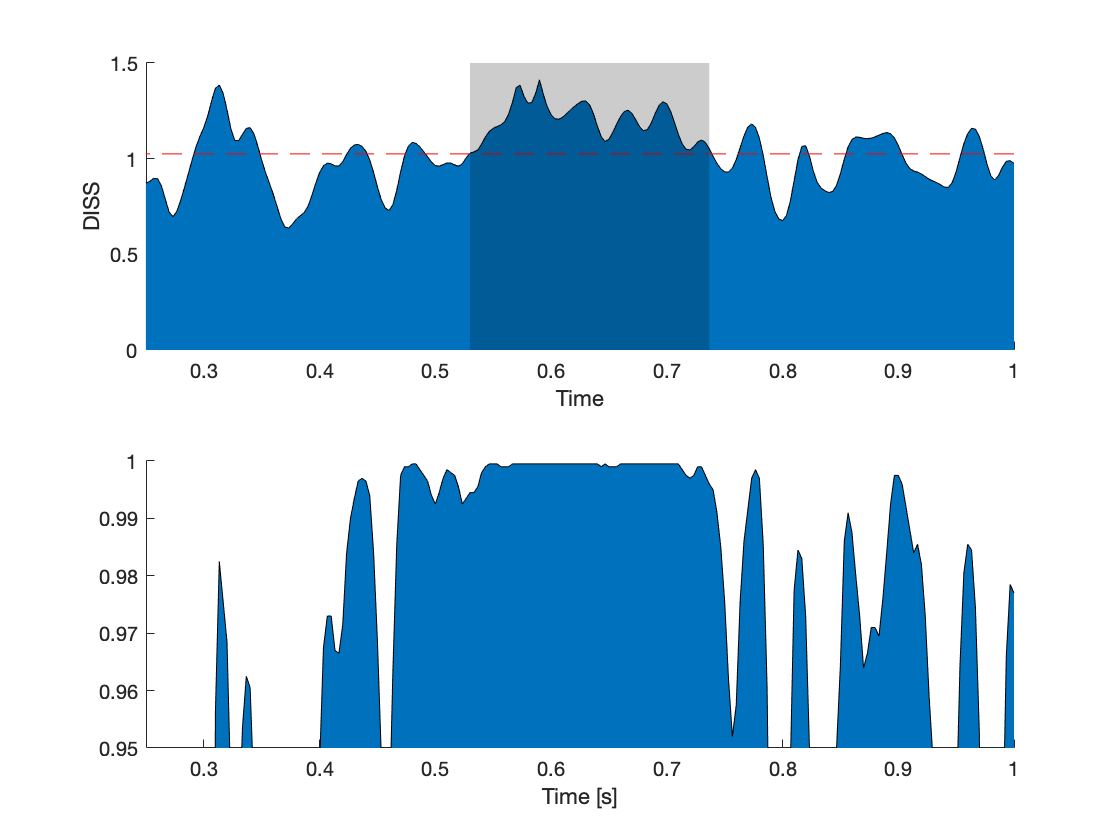

subplot(2,1,1)
microstate.functions.erp_TANOVA_plot(info_TANOVA,'clusterperm') ; xlim([0.25 1])
subplot(2,1,2)
microstate.functions.erp_TANOVA_plot(info_TANOVA,'millisecond') ; xlim([0.25 1])

### Perform microstate analysis

Next, we perform microstate analysis on all samples between 0-1 seconds following [3]. First, we calculate the grand average ERFs for each condition. To do this, use the **erp_grandaverage** function. The output of this function is a new *cohort* object with the same number of *individuals* as conditions, where each individual contains the grand average ERF for a given condition. In this case, the output will contain two *individuals*, one containing the grand average for the incongruent trials and one containing the grand average for congruent trials. 

% Calculate grand average ERPs
coh_grandavg = coh.erp_grandaverage 

coh_grandavg =   cohort with properties:

         individual: [2×1 microstate.individual]
          condition: [2×1 double]
    conditionlabels: {2×1 cell}
         globalmaps: []
              stats: [1×1 struct]
            process: [2×2 table]


Next, perform microstate analysis. Following the suggestions of [3], we use the Krzanowski-Lai criterion as this performs well for evoked data, and choose the optimum number of states >3 [3]. Unlike resting-state data, we will perform microstate analysis on the full ERF time series, specifying the name-value pair options `'finpeaks',false`. Name-value pair options also specify the Krzanowski-Lai criterion, as kneedle is default (`'criterion','KrzanowskiLai'`) and specify 4-10 clusters (`'kmin',4,'kmax',10`). 

Clustering microstates (4 to 10): 
k=3


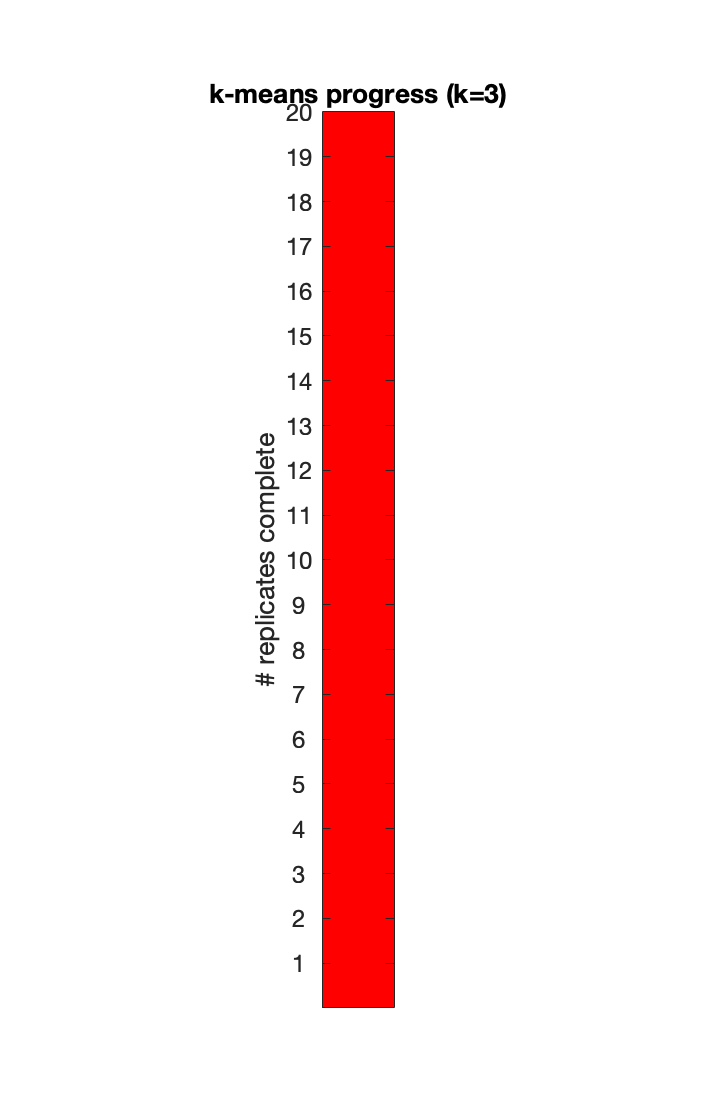

k=4


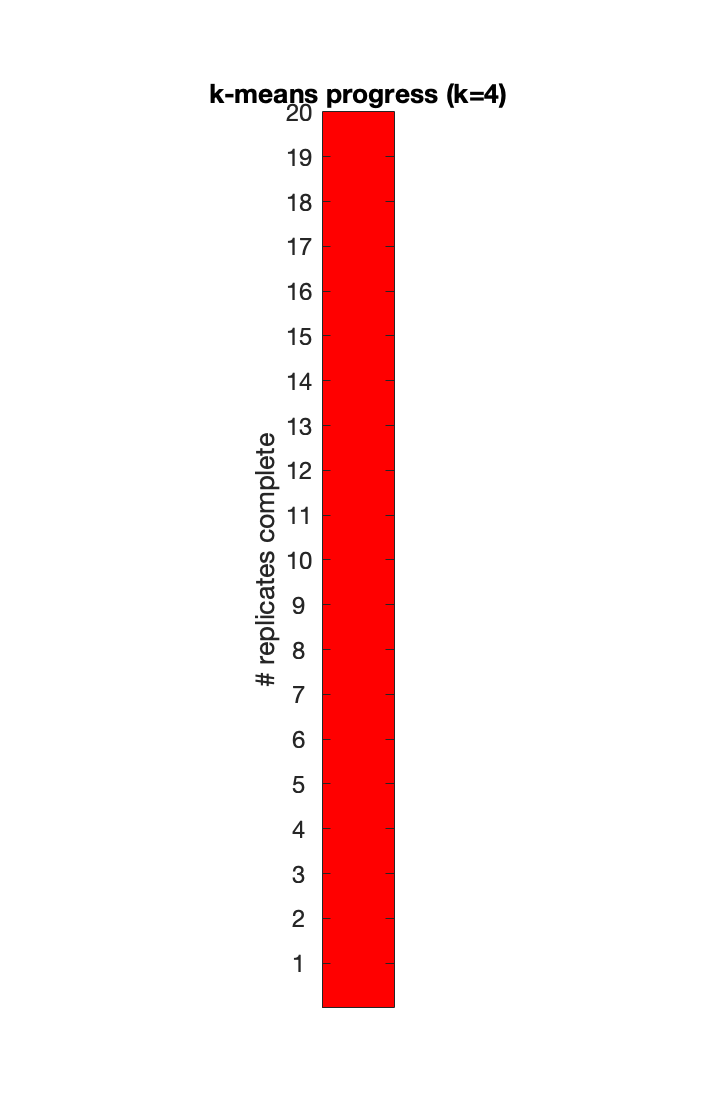

k=5


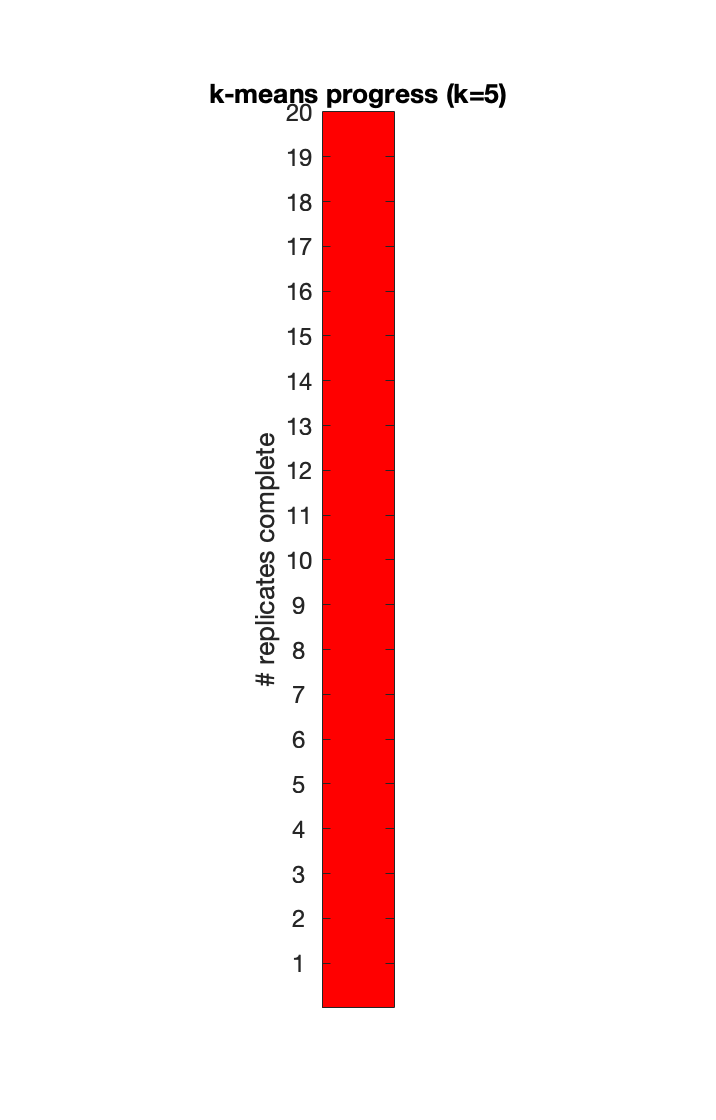

k=6


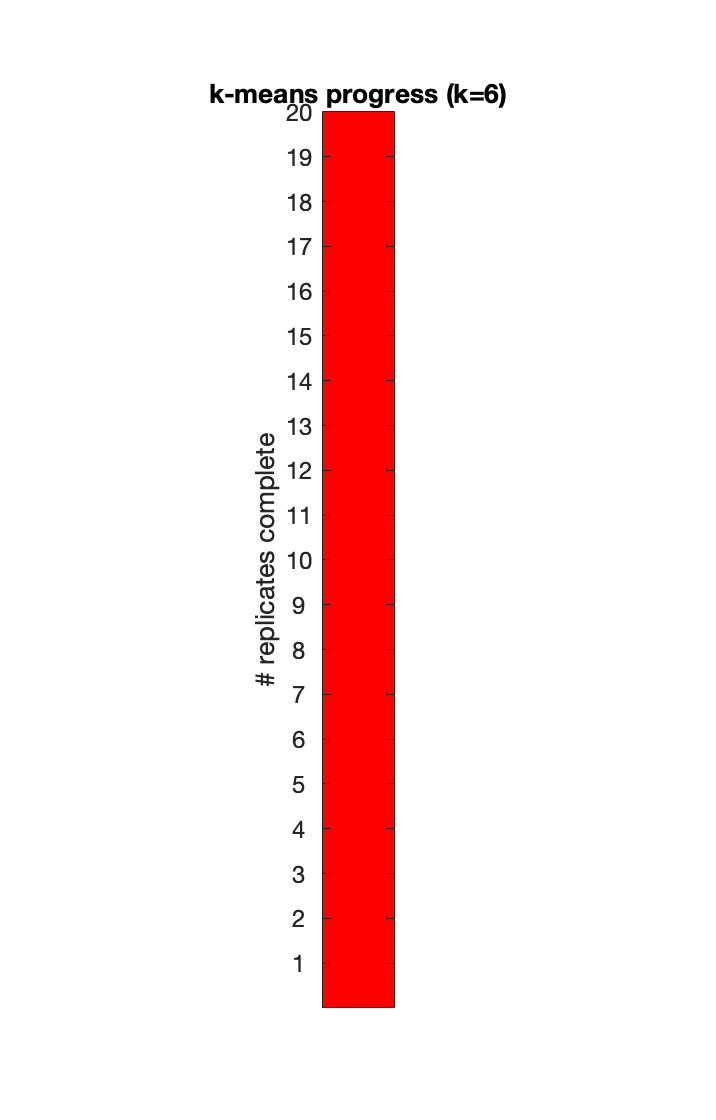

k=7


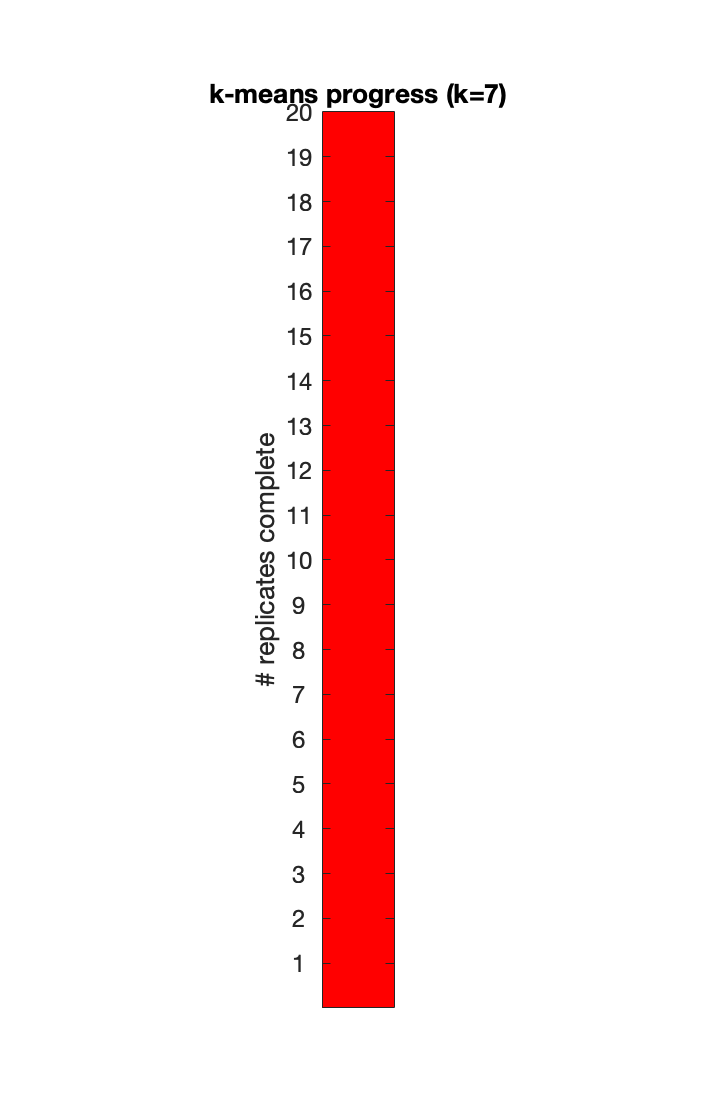

k=8


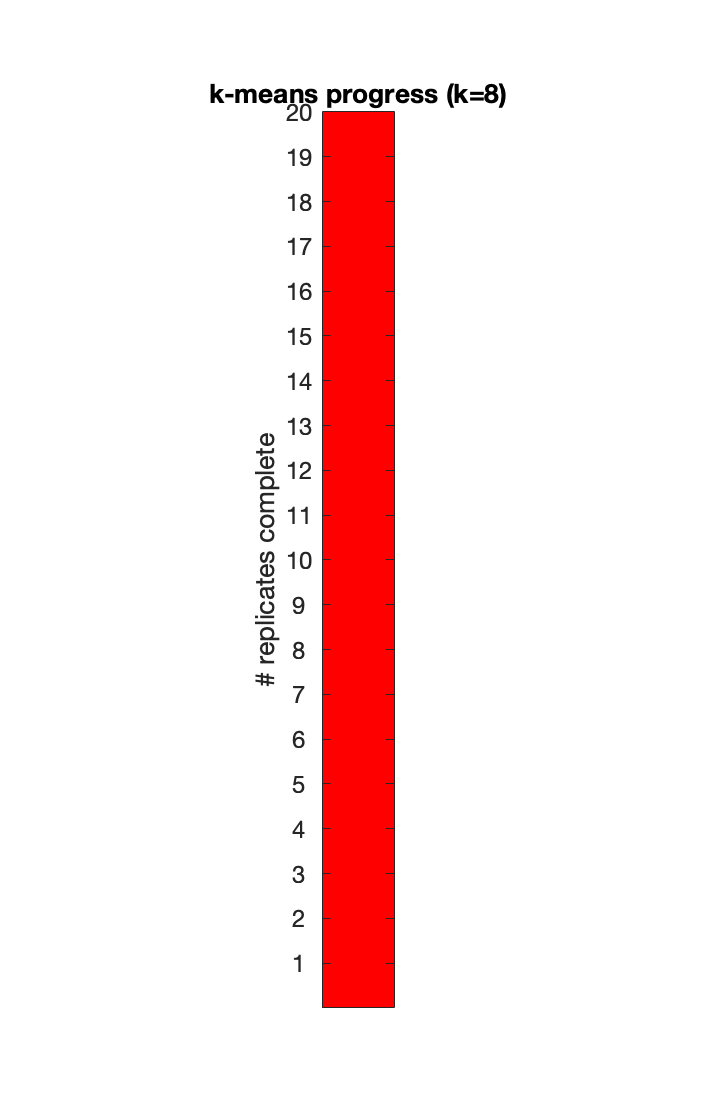

k=9


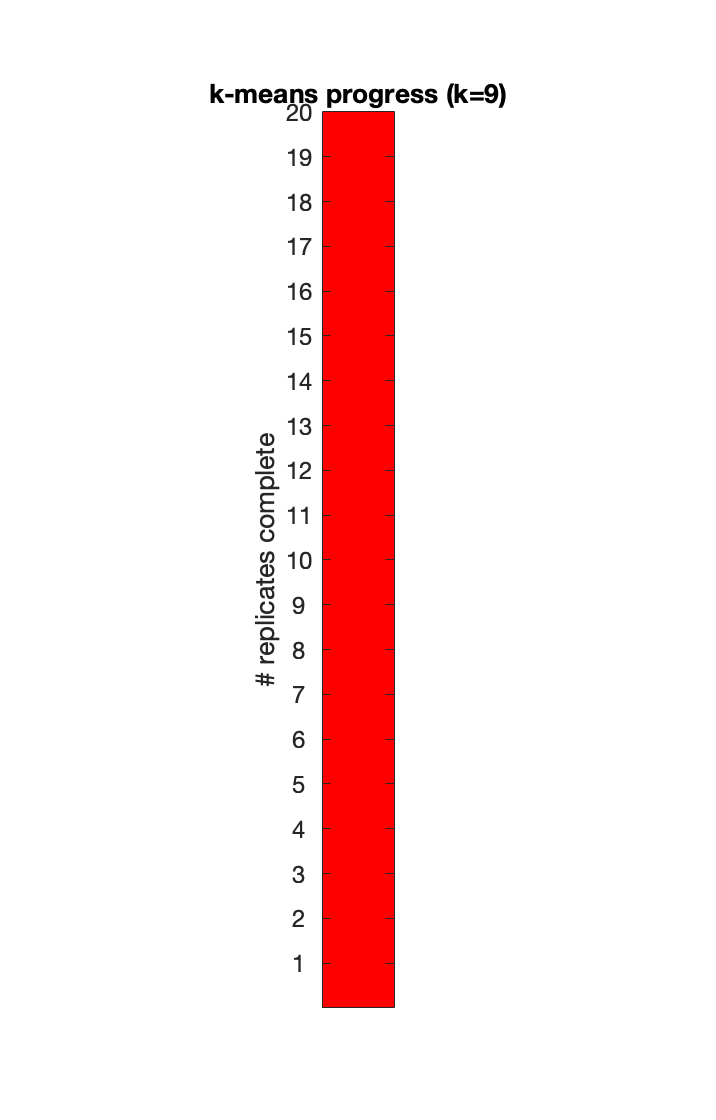

k=10


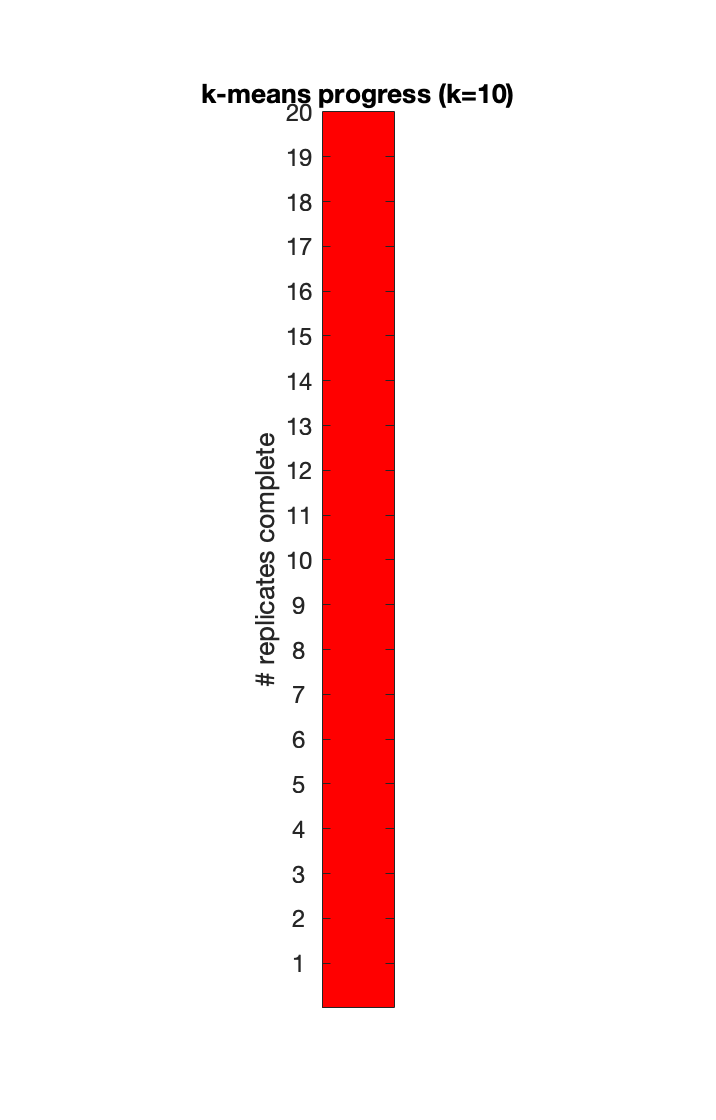

k=11


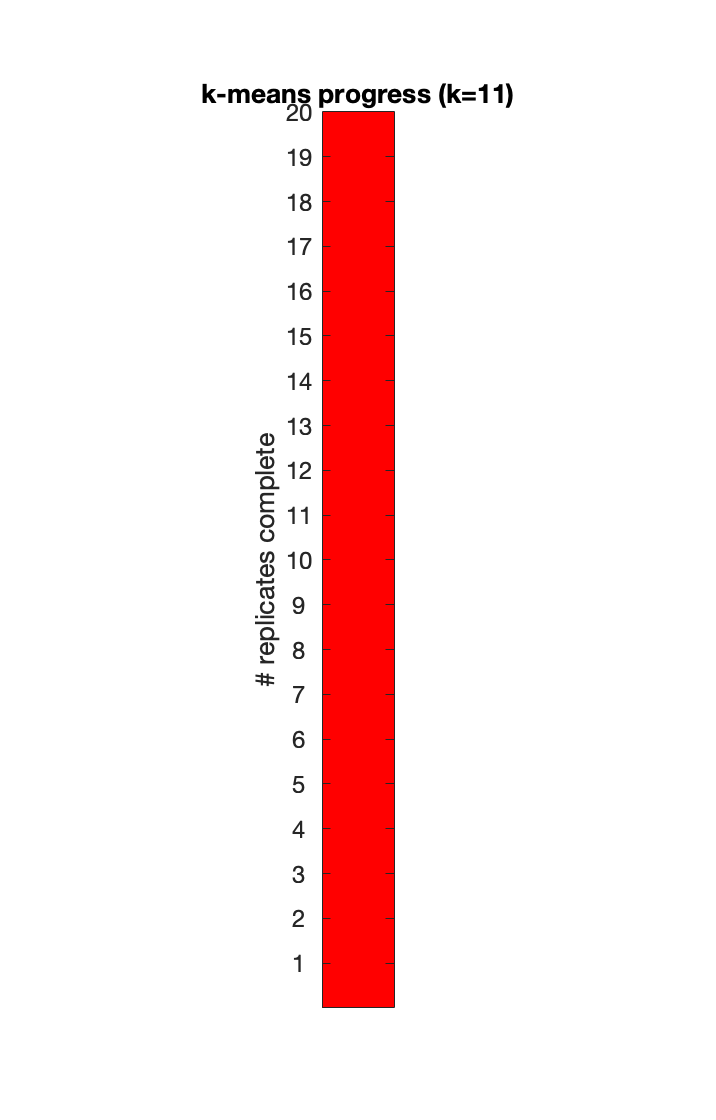

% Run microstate analysis
coh_grandavg = coh_grandavg.cluster_globalkoptimum('findpeaks',false,...
    'criterion','KrzanowskiLai','kmin',4,'kmax',10) ; 

You'll notice from the console output that clustering was performed for 3-11 states instead of 4-10. Since the Krzanowski-Lai criterion depends on curvature of the GEV, for a given value of k we need to know GEV(k-1), GEV(k), and GEV(k+1). Hence, Krzanowski-Lai will always cluster kmin-1 to kmax+1 states. 

### Analyse and visualise the microstate results

Finally, we will analyse and visualise the microstate results, testing the hypothesis that differences in activation of one of the microstate maps underpins the altered ERF topography in the data [1]. Firstly, plot the group level microstate maps. 

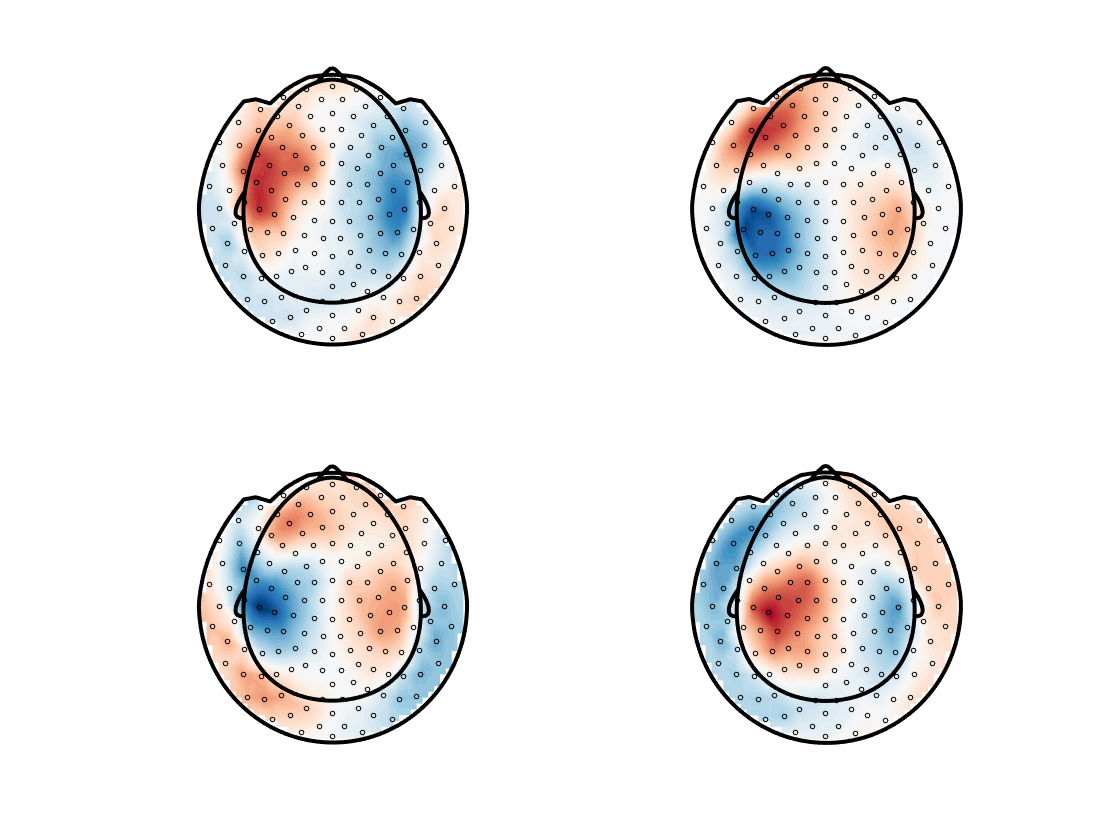

% load layout for plotting
layout = microstate.functions.layout_creator('ctf151',dataFIC_LP.label) ; 
figure
coh_grandavg.plot('globalmaps',layout) ; % plot the global maps

It is clear that map #2 closely corresponds to the spatial distribution of topographical differences in the ERF [1,2]. Therefore we will test the hypothesis that the coverage of map 2 differs between conditions in the range 530-736.7 ms (where our cluster permutation TANOVA identified differences). The first step to do this is to back-fit the global maps to the individual trials. Then, we select these time points from the data. The next step is to calculate coverage, before finally using a ranksum test to test for significant differences in coverage between conditions. 

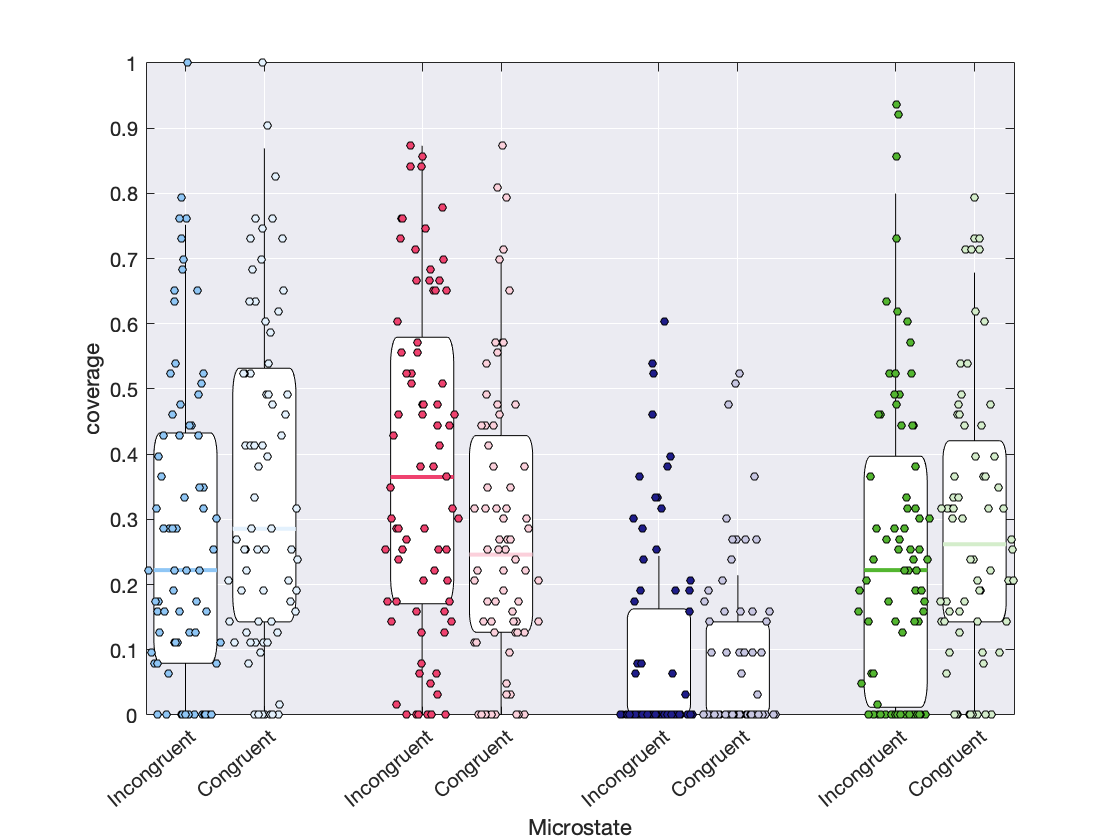

% Align maps to individuals
coh.globalmaps = coh_grandavg.globalmaps ;
coh = coh.cluster_globalmaps2individual ;

% Select only samples in the significantly different TANOVA zone
coh = microstate.functions.select_time(coh,info_TANOVA.maxcluster_time) ;

% Calculate stats
figure
coh = coh.ind_stats_coverage ; % calculate coverage
coh = coh.cohort_stats ; % concatenate statistics at group level
coh.plot('coverage') ;  % plot coverage
xtickangle(40)

p_coverage = ranksum(coh.stats(1).coverage(:,2),coh.stats(2).coverage(:,2))  % get p-value

p_coverage = 0.0151

We obtained a p-value of 0.0151, suggesting we can reject the null hypothesis. This supports our hypothesis that state 2 is more active in incongruent than congruent trials. 